## **Ejercicio 2. **

Genera 5 segundos de una onda cuadrada de frecuencia 800 Hz, pero representa sólo 0.005 segundos de la misma. Diseña un filtro FIR Hamming para extraer el armónico fundamental. Oye y representa tanto la señal original como la resultante. Nota: emplea el comando “filter()” para aplicar el filtro diseñado. Analiza los resultados.

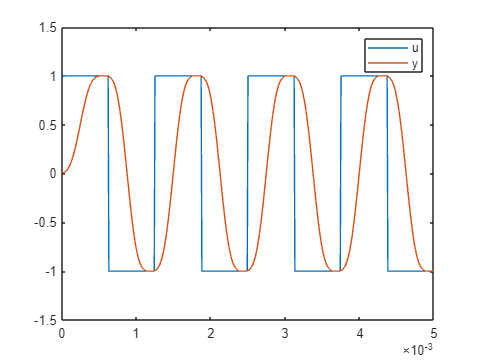

clear all
close all
fs = 100000;
fc = 1000/fs;
fu = 800;
wu = 2*pi*fu;
tiv = 1/fs;
t=0:tiv:(0.5-tiv);
u=square(wu*t);

N = 50;
hw = hamming(N+1);
numd = fir1(N,fc,hw);
dend = [1];

y = filter(numd,dend,u);
plot(t,u); hold on
plot(t,y)
axis([0 5e-3 -1.5 1.5])
legend('u','y');

sound(u,fs);
pause(length(u)/fs)
sound(y,fs)